% Question 2: sampling univariate gaussian
% using Gibbs sampling method

% Specically, sample from the joint posterior
% distribution of mu and precision for the
% mu and precision of the univariate Gaussian, 
% given some daa: 

% P(mu, lambda | x1, ... xN)

% We know the conditional distribution of the mean
% and the conditional distribution of the 
% precision lambda (they are the posteriors from
% module 2)

% Define the prior parameters: 
% mu0, sigma0 = prior parameters of mu, where
% mu ~ N(mu0, sigma0)

% a, b = prior parameters of precision (lambda), where
% lambda ~ Gamma(a, b)

% letting: 
mu0 = 0; 
sigma0 = sqrt(2);
a = 1; 
b = 1;


% Read the data: 
fileID = fopen('univarGauss.txt', 'r');
formatSpec = '%f'; 
data = fscanf(fileID, formatSpec)


% Posterior distributions of mu and lambda are: 
% for mu: mu ~ N(muN, sigmaN^2)
% for lambda: lambda ~ Gamma(aN, bN), 

% where the parameters are: 

% note: need lambda args since muN, lambdaN are the
% parameters of the MU posterior
muN = @(lambda) (mu0 + N * lambda * sigma0^2 * mean(X))/(1 + N * lambda * sigma0^2);
lambdaN = @(lambda) sigma0^2 / (1 + N*lambda * sigma0^2);

% note: need mu arg since these are the parameters of 
% the LAMBDA posterior.
aN = a + N/2;
bN = @(mu) b + (1/2) * sum(X - mu) .^ 2;


% Plot the posterior conditional distributions
% Plot for N = 0
N = 0; X = 0; 

Undefined function 'muN' for input arguments of type 'double'.

Error in Question2_GibbsSampleUnivarGaussian>plotPosteriors (line 70)
    plot(x, normpdf(x, muN(lambda_guess), lambdaN(lambda_guess)))

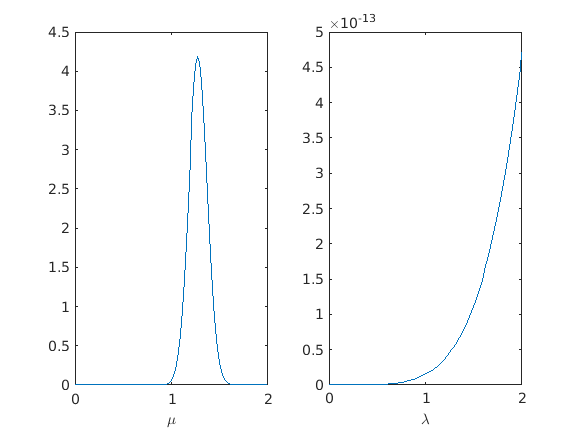

plotPosteriors

% Plots for N = 10
% WARNING: need to source the formulas again

N = 10; 
X = data(1:10, :); 

Undefined function 'muN' for input arguments of type 'double'.

Error in Question2_GibbsSampleUnivarGaussian>plotPosteriors (line 69)
    plot(x, normpdf(x, muN(lambda_guess), lambdaN(lambda_guess)))

plotPosteriors

% Plots for N = 100
% WARNING: need to source the formulas again

N = 100; 
X = data;

Undefined function 'muN' for input arguments of type 'double'.

Error in Question2_GibbsSampleUnivarGaussian>plotPosteriors (line 69)
    plot(x, normpdf(x, muN(lambda_guess), lambdaN(lambda_guess)))

plotPosteriors


% TO NOTICE: look how the guessed value of mu = 0
% leas to a distribution that gives low probability 
% of the target value of lambda  = 0.5. 
% This will be fixed using GIbbs sampling. 

function plotPosteriors
    x = linspace(0, 2);
    lambda_guess = 1; 
    mu_guess = 0; 
    subplot(1,2,1)
    plot(x, normpdf(x, muN(lambda_guess), lambdaN(lambda_guess)))
    xlabel('\mu')
    
    subplot(1,2,2)
    plot(x, gampdf(x, aN, bN(mu_guess)))
    xlabel('\lambda')
end


